1`a The wondowing parameters is chosen by looking at the part of the image which contains the bright spots. Due to they are bright, focusing on higher intensity pixels will pull the information out.`

`left = 80`

`right = 130`

img = imread('~/MatlabProjects/cs567hw2/1008_right.jpeg');
x = double(img);
% figure
% imshow(img(:,:,1));
% figure
% imshow(img(:,:,2));
% figure
% imshow(img(:,:,3));
left=80;
right=130;
x = -0.45*x(:,:,1) +2*x(:,:,2)-0.55*x(:,:,3);


1b The weight are chosen by looking at the r g b channals seperately. The spots seem to have the greatest contrast in the green channal, so giving it a higher weight will be helpful to bring out the lightest spots. While in other two channals, the contrast is not as big as in the green one, so if giving them the weights will bring out the other parts as well. Thus I end up gave them the negative weight.

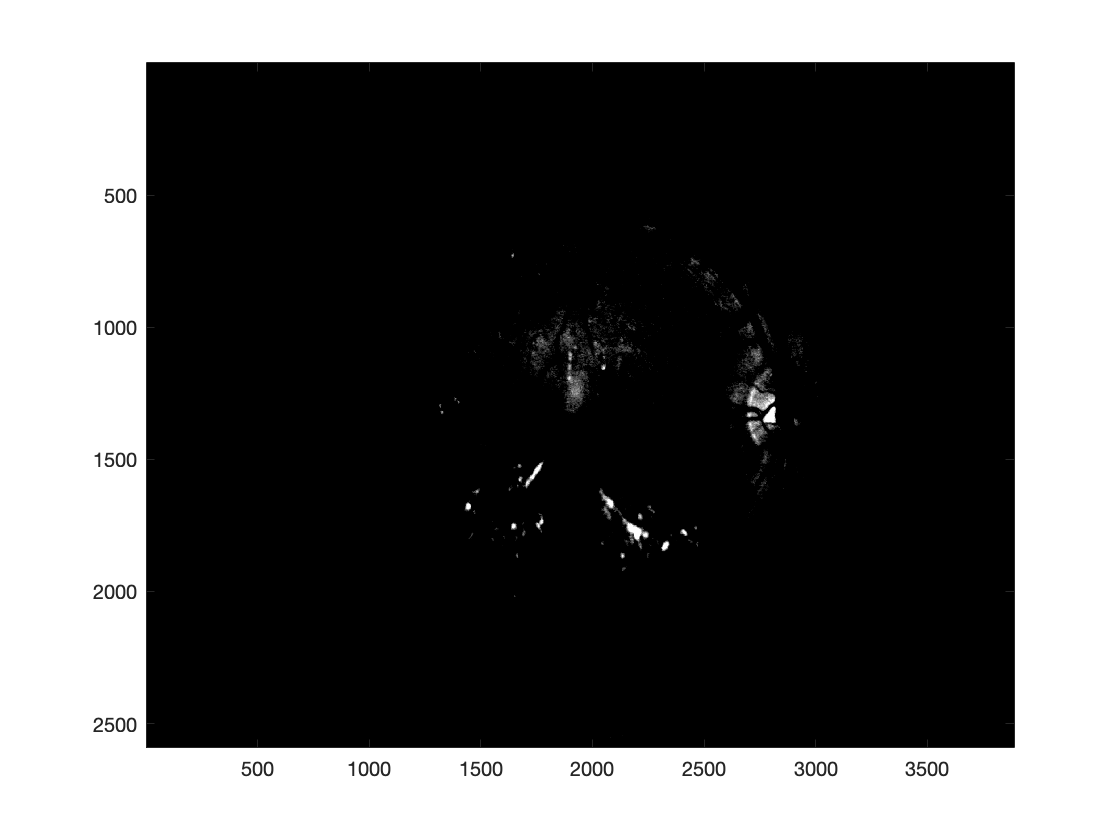

% 1c
imin = min(min(x));
imax = max(max(x));
x(x<left) = 0;
x(x>right) = 255;
x = floor((x-left)/(right-left)*64);
figure
image(x);
colormap(gray);

2a According to the max and min differeces of their value, which are both 0, it can be tell that the two images are exactly same

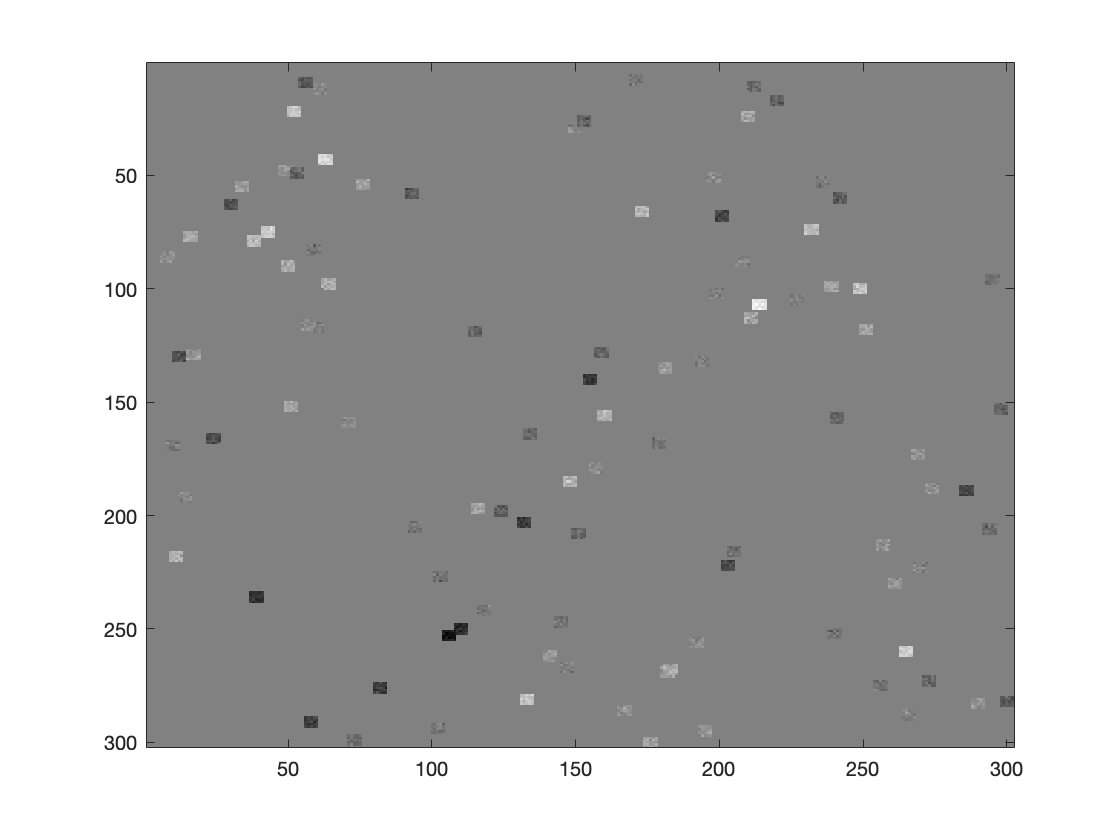

clear;
load('medfilt_problem_dat.mat');
img = zeros(304,304);
img(2:303,2:303)=dat;
double(dat);
medfilt = zeros(302,302);

for i=2:303
    for j= 2:303
        x = img(i-1:i+1,j-1:j+1);
        x = x(:);
        x = sort(x);
        medfilt(i-1,j-1) = x(5);
    end
end

medfilt2img = medfilt2(dat);

figure
imagesc(dat);
colormap(gray);

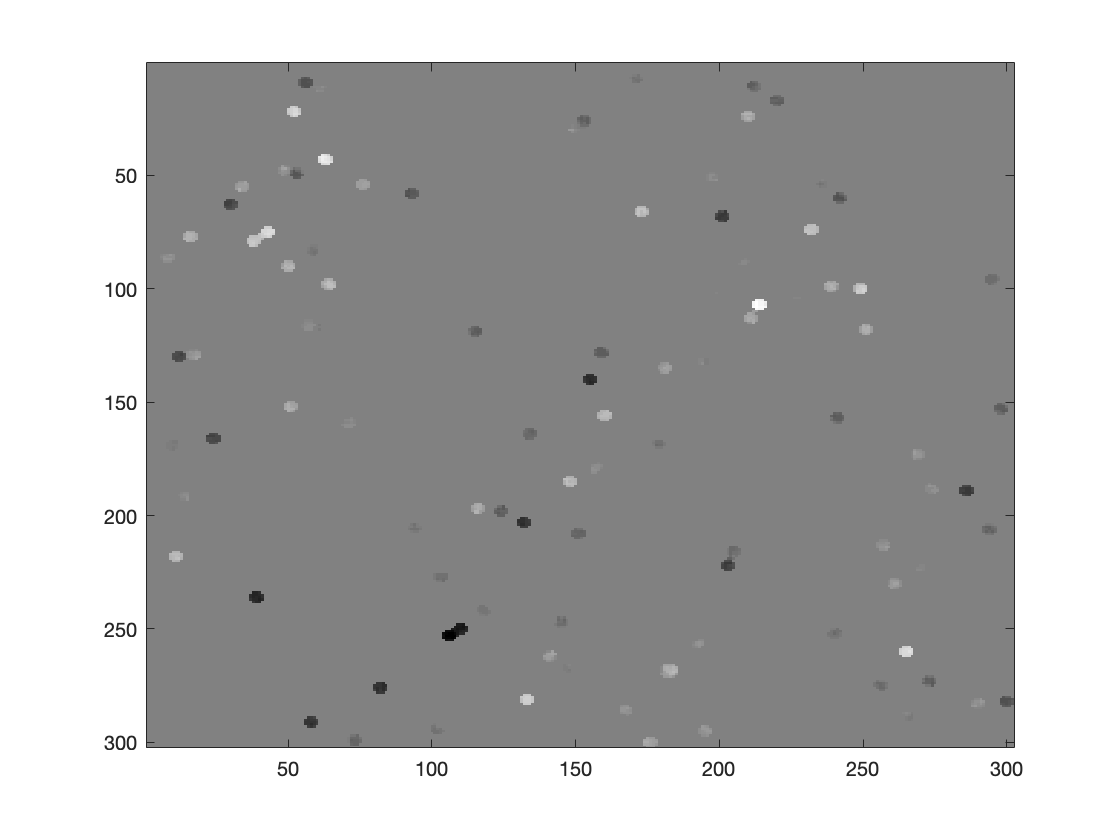


figure
imagesc(medfilt);
colormap(gray);


figure
imagesc(medfilt2img);
colormap(gray);


max(max(medfilt2img-medfilt))

ans = 0

min(min(medfilt2img-medfilt))

ans = 0

2b

If 2 peppers are connected, they takes up 5 x 10 pixels, which is too big for a 9 x 9 filter to "purify" (5x9 > half of 81). Thus, the min filter has to be 11 to remove all of the "salt and pepper"due to there is no 3 peppers in the image

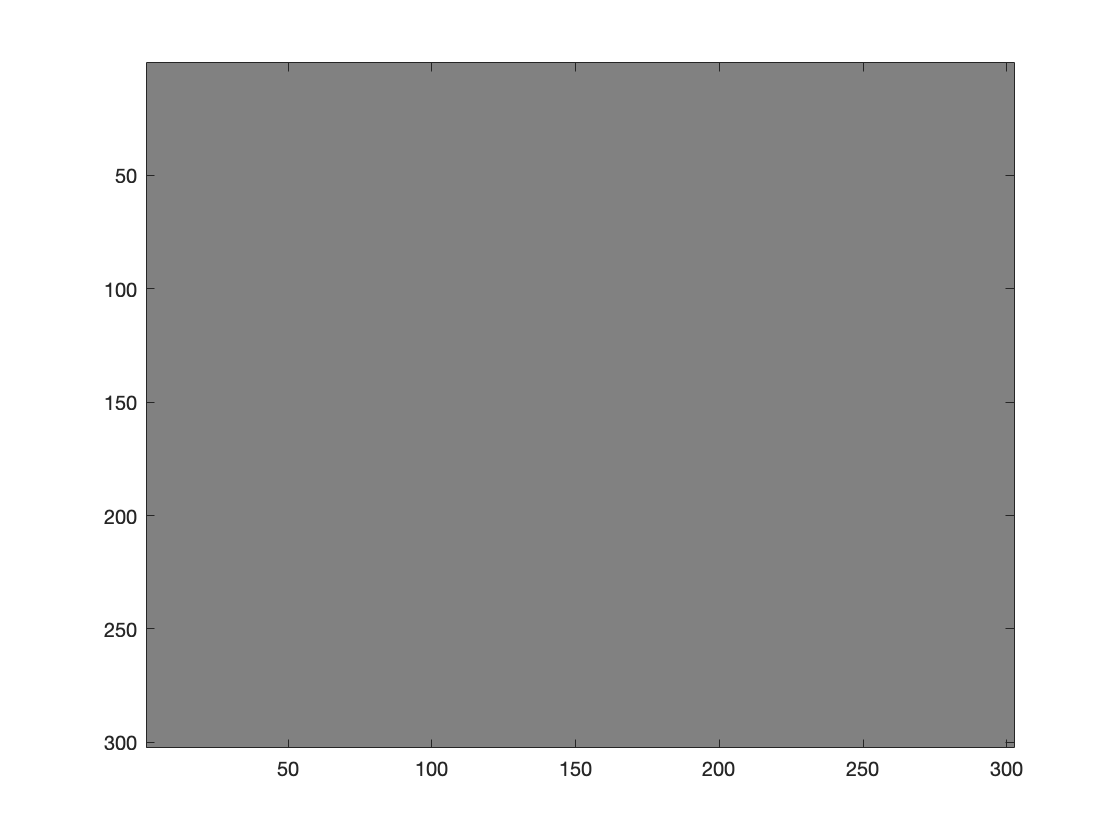

x = medfilt2(dat,[11,11]);
figure
imagesc(x);
colormap(gray);

2c 

The worst case for this questions is the filter cantains the whole isolated "pepper", which in case the #non-pepper part in it has to be greater than 25. Thus, the total size of the filter should be greater than 25+26 = 51. In case the filter can only be odd, it should at least be 9 x 9 > 51. The answer doesn't match the previous part since the given image consists many salt and pepper noice that next to or close to each other, while this filter is only good for removing the isolated noice

%3
clear;
load('dat_hough.mat');


Using median filter to remove artifact since it is great for removing high frenquency noise

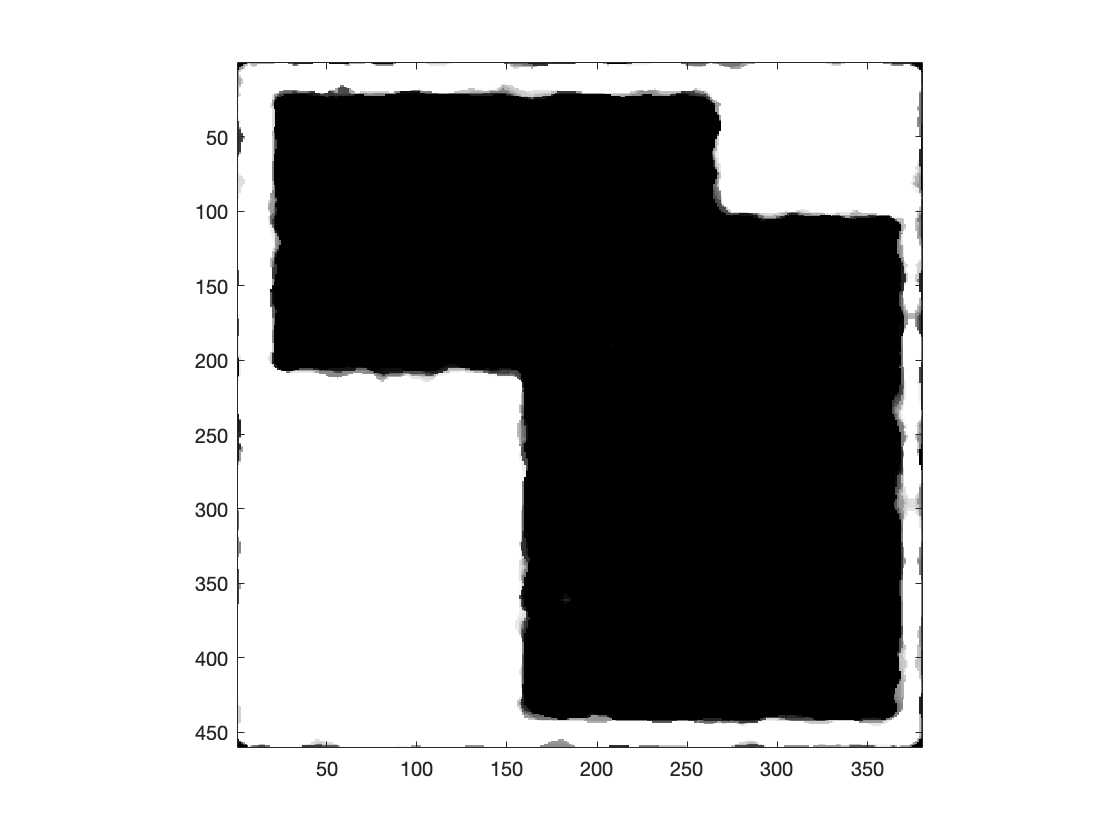

img = medfilt2(dat_hough,[14,14]);

figure
%subplot(1,3,1);
imagesc(img);
colormap(gray);
axis('square');

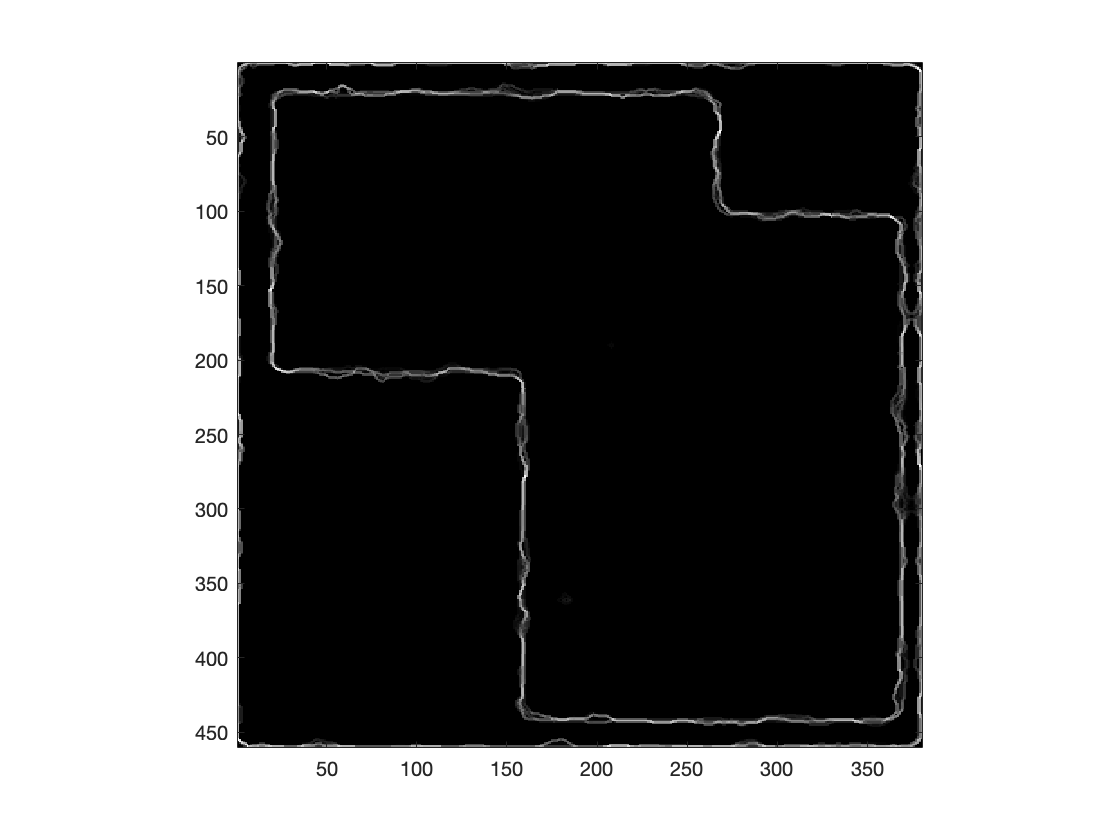


ky = zeros(3,3);
ky(2,1) = 1;
ky(2,3) = -1;
ky = 0.5*ky;
kx = zeros(3,3);
kx(1,2) = 1;
kx(3,2) = -1;
kx = 0.5*kx;

x = conv2(img, kx, 'same');
y = conv2(img, ky, 'same');
img = sqrt(x.^2 + y.^2);

%subplot(1,3,2);
figure
imagesc(img);
colormap(gray);
axis('square');

img = img>12;

Using central difference filter to find edges in both x and y axises and calculating the length of the gradient in the image afterwards. The reason I prefer his method because finding the gradient will give a close estimate of potential edge pixels.

Setting a threshold to convert the image into binary and treate every pixels below it as 0, above it as 1.

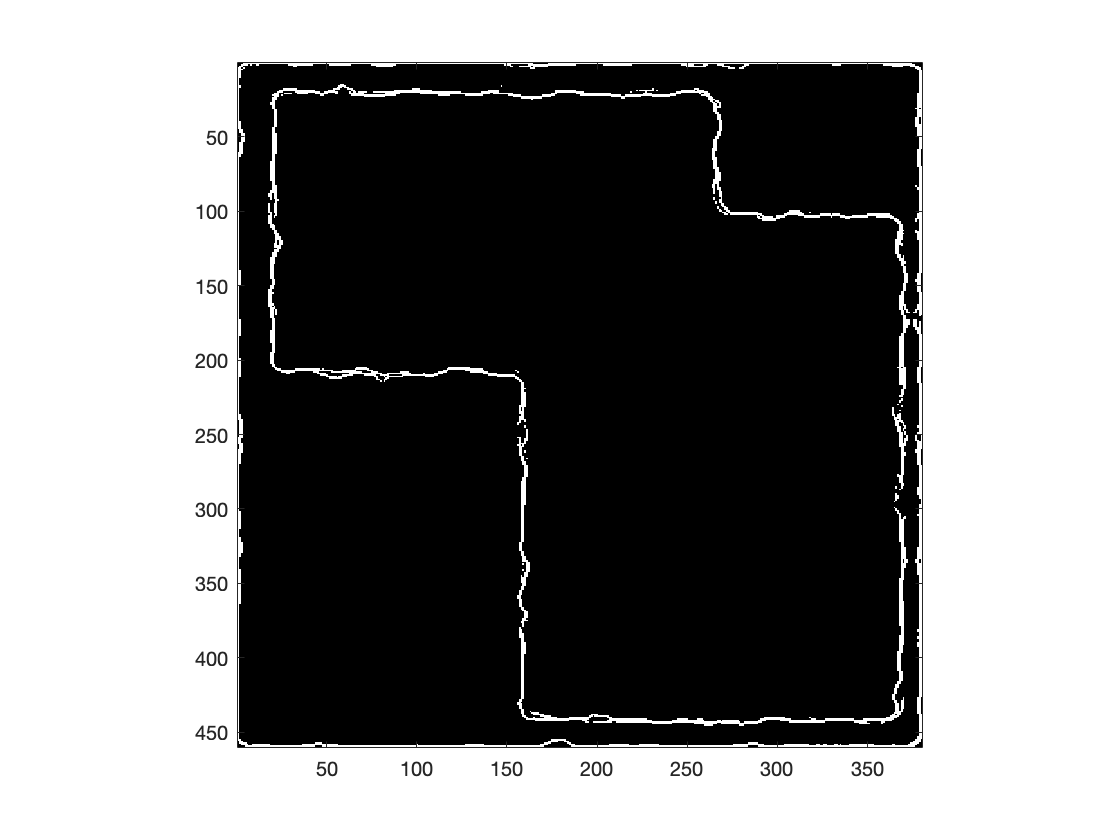

%subplot(1,3,3);
figure
imagesc(img);
colormap(gray);
axis('square');

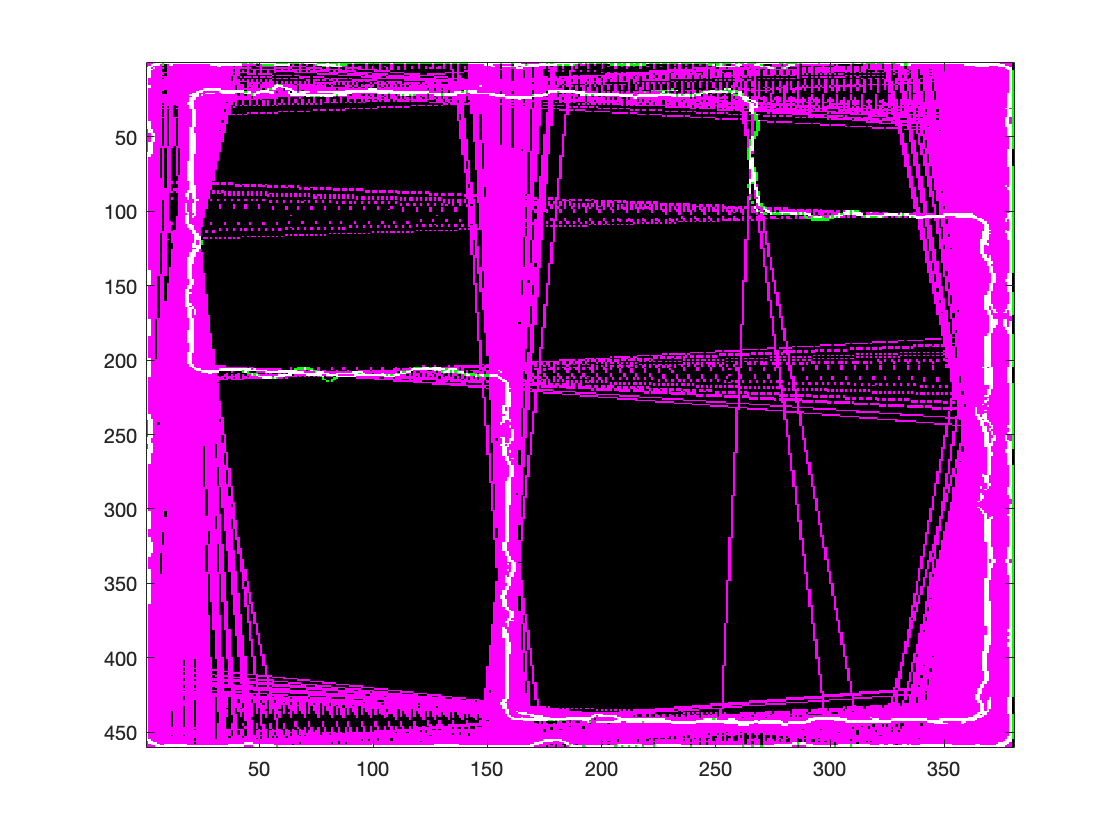


% here I used the hough_trans code from class
[himg, theta, r] = hough_trans(img);

maxint=max(max(himg));
[i, j] = find(himg > 0.115*maxint);

theta_rad = theta*pi/180;

slope = -1*cos(theta_rad(j))./sin(theta_rad(j));
intercepts = r(i)./sin(theta_rad(j));

img_lines = zeros(size(img));
n_lines = length(slope);
for i = 1:n_lines
  xval = [1:0.1:size(img,1)]'; 
  yval = intercepts(i) + xval*slope(i);
  xval = floor(xval);
  yval = floor(yval);
  keep = yval< size(img,2) & yval>0;
  xval_keep = xval(keep);
  yval_keep = yval(keep);
  for index = 1:length(xval_keep)
     img_lines(xval_keep(index), yval_keep(index)) = 1;
  end
end

fused_img = imfuse(img, img_lines);
figure
imagesc(fused_img);
colormap(gray);

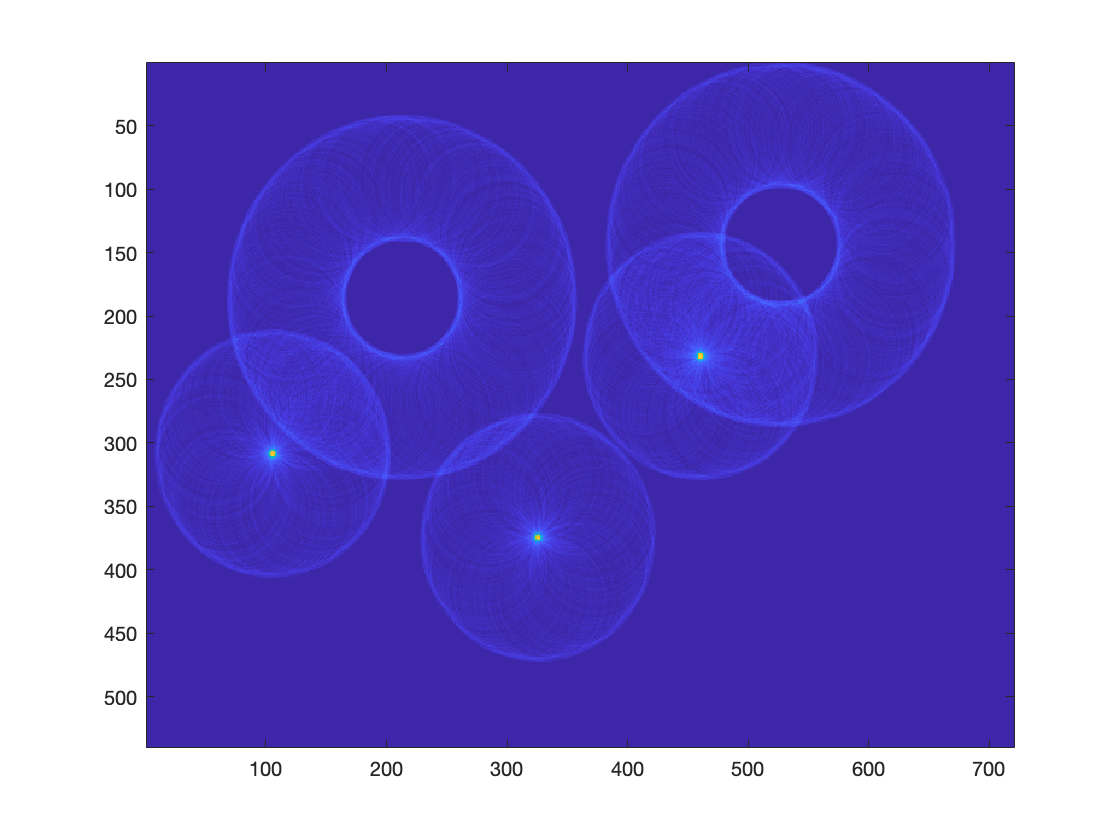

%4
load('img_circle.mat');

accum = zeros(540,720,3);

i_rng = size(img_circle, 1);
j_rng = size(img_circle, 2);


for i=1:i_rng
    for j=1:j_rng
        if img_circle(i,j) > 0
            for r=48:2:52
                for t=0:359
                    x = i-r*cos(t*pi/180);
                    y = j-r*sin(t*pi/180);
                    if(round(x)>0 & round(x)<=size(img_circle,1) & round(y)>0 & round(y)<=size(img_circle,2))
                        accum(round(x), round(y), (r-46)/2) = accum(round(x), round(y), (r-46)/2)+1;
                    end
                end
            end
        end
    end
end

max_score = max(max(accum(:)));

[a,b,c] = find(accum == max_score);

bestR = c;% 1 == 48, 2 == 50, 3 == 52

[x,y,r] = find(accum > max_score * 0.8);

figure
imagesc(accum(:,:,bestR));

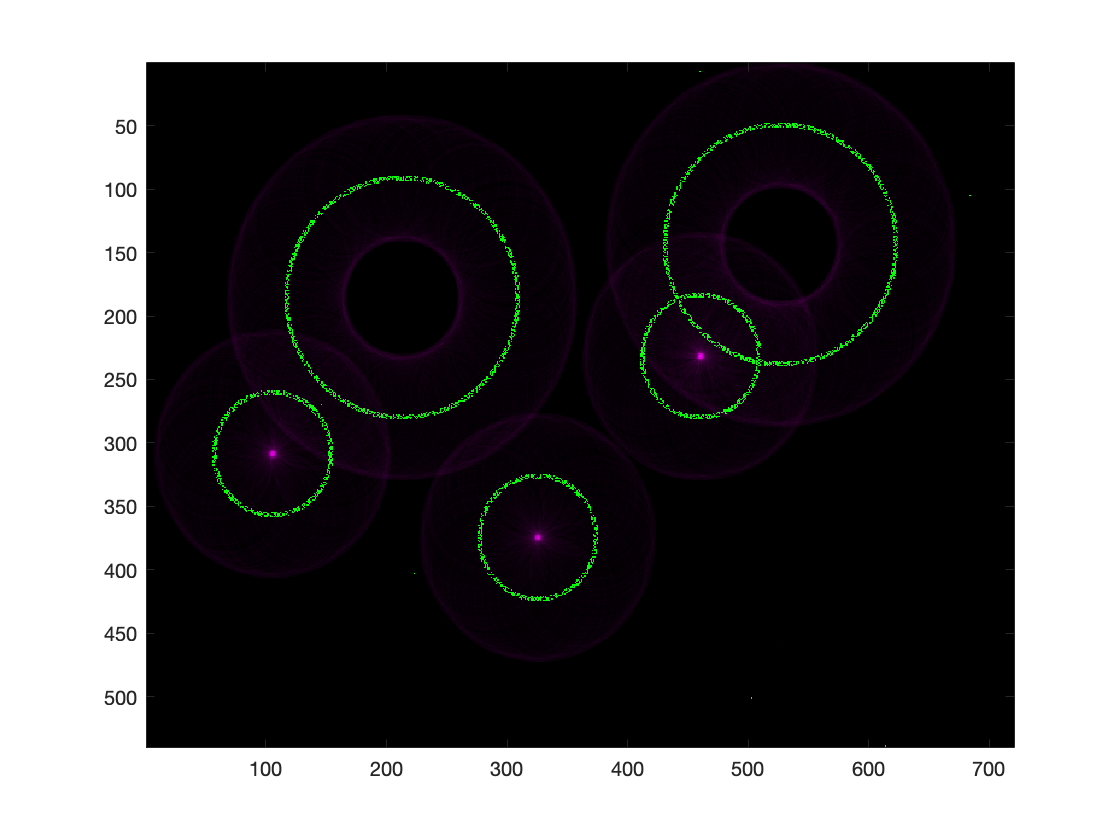


fused = imfuse(img_circle,accum(:,:,bestR));

figure
imagesc(fused);